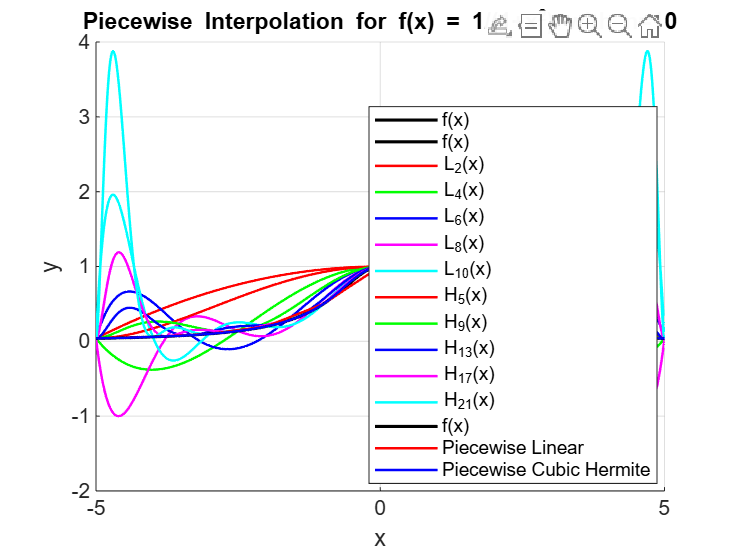

% Define the function f(x) = 1/(1+x^2)
f = @(x) 1./(1+x.^2);
df = @(x) -2*x./((1+x.^2).^2); % Derivative of f(x) for Hermite interpolation

% Define the interval
a = -5;
b = 5;

% Number of points for plotting the original function
x_plot = linspace(a, b, 1000);
y_plot = f(x_plot);

% Create figure for Lagrange interpolation
figure(1);
hold on;
plot(x_plot, y_plot, 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');

% Create figure for Hermite interpolation
figure(2);
hold on;
plot(x_plot, y_plot, 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');

% Define colors for different n values
colors = {'r', 'g', 'b', 'm', 'c'};

% (1) Lagrange interpolation for n = 2,4,6,8,10
for n_idx = 1:5
    n = 2*n_idx;
    x_nodes = linspace(a, b, n+1);
    y_nodes = f(x_nodes);
    
    % Compute Lagrange interpolation
    y_lagrange = zeros(size(x_plot));
    for i = 1:length(x_plot)
        y_lagrange(i) = lagrange_interpolation(x_nodes, y_nodes, x_plot(i));
    end
    
    % Plot Lagrange interpolation
    figure(1);
    plot(x_plot, y_lagrange, [colors{n_idx} '-'], 'LineWidth', 1.2, 'DisplayName', ['L_{' num2str(n) '}(x)']);
end

% (2) Hermite interpolation for n = 2,4,6,8,10
for n_idx = 1:5
    n = 2*n_idx;
    x_nodes = linspace(a, b, n+1);
    y_nodes = f(x_nodes);
    dy_nodes = df(x_nodes);
    
    % Compute Hermite interpolation
    y_hermite = zeros(size(x_plot));
    for i = 1:length(x_plot)
        y_hermite(i) = hermite_interpolation(x_nodes, y_nodes, dy_nodes, x_plot(i));
    end
    
    % Plot Hermite interpolation
    figure(2);
    plot(x_plot, y_hermite, [colors{n_idx} '-'], 'LineWidth', 1.2, 'DisplayName', ['H_{' num2str(2*n+1) '}(x)']);
end

% (3) For n=10: Piecewise linear and cubic Hermite interpolation
n = 10;
x_nodes = linspace(a, b, n+1);
y_nodes = f(x_nodes);
dy_nodes = df(x_nodes);

% Compute piecewise linear interpolation
y_piecewise_linear = zeros(size(x_plot));
for i = 1:length(x_plot)
    y_piecewise_linear(i) = piecewise_linear_interpolation(x_nodes, y_nodes, x_plot(i));
end

% Compute piecewise cubic Hermite interpolation
y_piecewise_hermite = zeros(size(x_plot));
for i = 1:length(x_plot)
    y_piecewise_hermite(i) = piecewise_cubic_hermite_interpolation(x_nodes, y_nodes, dy_nodes, x_plot(i));
end

% Create figure for piecewise interpolation
figure(3);
hold on;
plot(x_plot, y_plot, 'k-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');
plot(x_plot, y_piecewise_linear, 'r-', 'LineWidth', 1.2, 'DisplayName', 'Piecewise Linear');
plot(x_plot, y_piecewise_hermite, 'b-', 'LineWidth', 1.2, 'DisplayName', 'Piecewise Cubic Hermite');

% Add legends and labels to all figures
for fig_idx = 1:3
    figure(fig_idx);
    legend('Location', 'best');
    
xlim([-4.45 2.38])
ylim([-1.96 2.14])
    xlabel('x');
    ylabel('y');
    grid on;
    
    if fig_idx == 1
        title('Lagrange Interpolation for f(x) = 1/(1+x^2)');
    elseif fig_idx == 2
        title('Hermite Interpolation for f(x) = 1/(1+x^2)');
    else
        title('Piecewise Interpolation for f(x) = 1/(1+x^2) with n=10');
    end
end


% Function to compute Lagrange interpolation
function y = lagrange_interpolation(x_nodes, y_nodes, x)
    n = length(x_nodes) - 1;
    y = 0;
    
    for i = 1:n+1
        L = 1;
        for j = 1:n+1
            if j ~= i
                L = L * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        y = y + y_nodes(i) * L;
    end
end

% Function to compute Hermite interpolation
function y = hermite_interpolation(x_nodes, y_nodes, dy_nodes, x)
    n = length(x_nodes);
    y = 0;
    
    for i = 1:n
        h = 1;
        dh = 0;
        for j = 1:n
            if j ~= i
                h = h * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
                dh = dh + 1 / (x_nodes(i) - x_nodes(j));
            end
        end
        y = y + y_nodes(i) * (1 - 2 * (x - x_nodes(i)) * dh) * h^2;
        y = y + dy_nodes(i) * (x - x_nodes(i)) * h^2;
    end
end

% Function to compute piecewise linear interpolation
function y = piecewise_linear_interpolation(x_nodes, y_nodes, x)
    n = length(x_nodes);
    
    % Handle out-of-range x values
    if x <= x_nodes(1)
        y = y_nodes(1);
        return;
    elseif x >= x_nodes(end)
        y = y_nodes(end);
        return;
    end
    
    % Find the interval containing x
    for i = 1:n-1
        if x >= x_nodes(i) && x <= x_nodes(i+1)
            % Linear interpolation
            t = (x - x_nodes(i)) / (x_nodes(i+1) - x_nodes(i));
            y = (1-t) * y_nodes(i) + t * y_nodes(i+1);
            return;
        end
    end
end

% Function to compute piecewise cubic Hermite interpolation
function y = piecewise_cubic_hermite_interpolation(x_nodes, y_nodes, dy_nodes, x)
    n = length(x_nodes);
    
    % Handle out-of-range x values
    if x <= x_nodes(1)
        y = y_nodes(1);
        return;
    elseif x >= x_nodes(end)
        y = y_nodes(end);
        return;
    end
    
    % Find the interval containing x
    for i = 1:n-1
        if x >= x_nodes(i) && x <= x_nodes(i+1)
            % Cubic Hermite interpolation
            h = x_nodes(i+1) - x_nodes(i);
            t = (x - x_nodes(i)) / h;
            
            h00 = 2*t^3 - 3*t^2 + 1;
            h10 = t^3 - 2*t^2 + t;
            h01 = -2*t^3 + 3*t^2;
            h11 = t^3 - t^2;
            
            y = h00 * y_nodes(i) + h10 * h * dy_nodes(i) + h01 * y_nodes(i+1) + h11 * h * dy_nodes(i+1);
            return;
        end
    end
end